# Bi-linear Transformation for the Routh-Hurwitz Criterion: Critical Transformation Scenarios & MATLAB

## The Bilinear Transformation: a Recap


$$z = \frac{w+1}{w-1}, \; z, \, w \in \mathbb C
\quad \quad \quad \quad\quad
\begin{array}{l}
\vert z \vert < 1 \, \, \Longleftrightarrow \, \, {\rm Re} (w) < 0 \\
\vert z \vert = 1 \, \, \Longleftrightarrow \, \, {\rm Re} (w) = 0 \\
\vert z \vert > 1 \, \, \Longleftrightarrow \, \, {\rm Re} (w) > 0
\end{array}$$


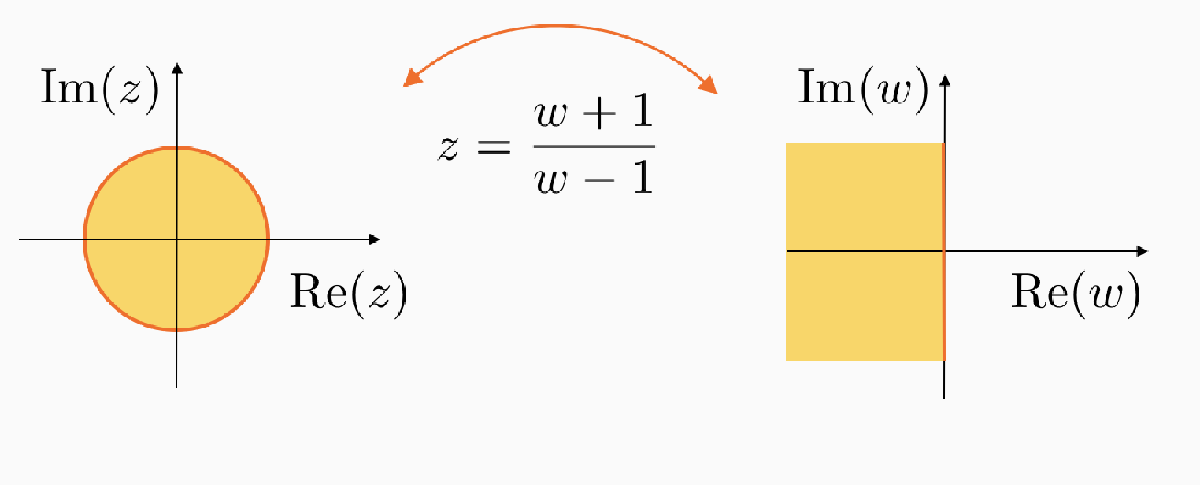

Substitute

 
$$z = \frac{w+1}{w-1}, \; z, \, w \in \mathbb C$$


into $p_A (z)  =
\varphi_0 z^n + \varphi_1 z^{n-1} + \cdots
+ \varphi_{n-1} z + \varphi_n$, thus obtaining


$$\begin{array}{l}
q_A (w)  = \, \left(w-1 \right)^n \,   \left[
\varphi_0 \frac{\left(w+1 \right)^n}{\left(w-1 \right)^n} + 
 \varphi_1 \frac{\left(w+1 \right)^{n-1}}{\left(w-1 \right)^{n-1}} + \cdots +
 \varphi_{n-1} \frac{\left(w+1 \right)}{\left(w-1 \right)} 
 +  \varphi_{n}
 \right ]
\end{array}$$


and hence one gets


$$q_A(w) = q_0 \, w^n + q_1\,w^{n-1}+\cdots+q_{n-1}\,w + q_n$$


with suitable coefficients $q_0, \, q_1, \ldots, q_n$.

## Properties of the Bilinear Transformation

### Transformed Polynomial vs Original Polynomial: the General Scenario

Given a generic polynomial of the complex variable $z$, with polynomial degree $n$, without any root in $z=1$ (please, check this particular scenario below in this document)


$$p_A (z)  =
\varphi_0 z^n + \varphi_1 z^{n-1} + \cdots
+ \varphi_{n-1} z + \varphi_n$$


the transformed polynomial $q_{A}(w)$ has **always** the same degree $n$.


$$\begin{array}{l}
q_A (w)  = \, \left(w-1 \right)^n \,   \left[
\varphi_0 \frac{\left(w+1 \right)^n}{\left(w-1 \right)^n} + 
 \varphi_1 \frac{\left(w+1 \right)^{n-1}}{\left(w-1 \right)^{n-1}} + \cdots +
 \varphi_{n-1} \frac{\left(w+1 \right)}{\left(w-1 \right)} 
 +  \varphi_{n}
 \right ]
\end{array}$$


In fact, after some algebra


$$\begin{array}{l}
q_A (w)  = \, 
\varphi_0 \left(w+1 \right)^n + 
 \varphi_1 \left(w+1 \right)^{n-1}\,\left(w-1 \right) + \cdots +
 \varphi_{n-1} \left(w+1 \right)\, \left(w-1 \right)^{n-1}
 +  \varphi_{n}\, \left(w-1 \right)^{n}
 
\end{array}$$


thus, $q_{A}(w)$ is, in general, a linear combination of polynomials of the variable $w$, each with the same degree $n$.

### Critical Scenario

What if one of the roots of the polynomial $p(z)$ is $z=1$?

Let us suppose


$$p(z) = \left(z-1\right)^{n_1} \cdot \displaystyle \prod_{i=2}^{\sigma} \left(z-\lambda_{i}\right)^{n_i} \qquad \sum_{i=1}^{\sigma} n_i = n$$


Applying the bilinear transform, we obtain


$$q(w) = \left(w-1\right)^{n} \cdot \left(\frac{w+1}{w-1}-1\right)^{n_1} \cdot \displaystyle \prod_{i=2}^{\sigma} \left(\frac{w+1}{w-1}-\lambda_{i}\right)^{n_i} \quad \Longrightarrow \quad 
q(w) = \left(w-1\right)^{n} \cdot \left(\frac{w+1-w+1}{w-1}\right)^{n_1} \cdot \displaystyle \prod_{i=2}^{\sigma} \left(\frac{w+1-\lambda_i \left( w-1\right)}{w-1} \right)^{n_i} $$


After some simple algebra


$$q(w) = \left(w-1\right)^{n} \cdot\frac{2^{n_1}}{(w-1)^{n_1}} \cdot \displaystyle \prod_{i=2}^{\sigma} \left(\frac{w+1-\lambda_i \left( w-1\right)}{w-1} \right)^{n_i} \quad \Longrightarrow \quad q(w) = 2^{n_1}\cdot \left(w-1\right)^{n-n_1} \cdot \displaystyle \prod_{i=2}^{\sigma} \left(\frac{w+1-\lambda_i \left( w-1\right)}{w-1} \right)^{n_i}$$


Please, note: the polynomial $q(w)$ has no more degree $n$: the degree is indeed $n-n_1$.

The polynomials at the numerator and at the denominator in the product term are polynomials at most of degree $n-n_1$, so this is the degree of the polynomial $q(w)$.

Let us replicate this behavior of the bilinear transform using the *Symbolic Math Toolbox* in MATLAB.

clear
close all
clc

syms z w % let's declare a few symbolic variables

p_Az = (z-1)^2*(z+0.5)^3*(z+2)^4 % assign the characteristic polynomial 

$$p\_Az = {\left(z-1\right)}^{2}\,{\left(z+2\right)}^{4}\,{\left(z+\frac{1}{2}\right)}^{3}$$

  
collect(p_Az,z)

$$ans = z^{9}+\frac{15\,z^{8}}{2}+\frac{75\,z^{7}}{4}+\frac{81\,z^{6}}{8}-\frac{57\,z^{5}}{2}-\frac{327\,z^{4}}{8}-3\,z^{3}+21\,z^{2}+12\,z+2$$

So the degree of the polynoial is 9. Let us apply the bilinear transform



bTexpr = (w+1)/(w-1) % the bilinear transform                     

$$bTexpr = \frac{w+1}{w-1}$$

Now, using the `subs` command, let us compute the transformed polynomial

q_Aw = ((w-1)^9) * subs(p_Az,z,bTexpr)

$$q\_Aw = {\left(\frac{w+1}{w-1}-1\right)}^{2}\,{\left(\frac{w+1}{w-1}+2\right)}^{4}\,{\left(\frac{w+1}{w-1}+\frac{1}{2}\right)}^{3}\,{\left(w-1\right)}^{9}$$

Finally, let us simplify the resulting expression

q_Aw = simplify(q_Aw)

$$q\_Aw = \frac{{\left(3\,w-1\right)}^{4}\,{\left(3\,w+1\right)}^{3}}{2}$$

Note: the degree of $q(w)$ is 7, not 9! 

Indeed, when you detect that applying the bilinear transform the degree of the transformed polynomial is lower than the degree of the original polynomial, then you can state that ta root of the original polynomial $p(z)$is $z=+1$. Moreover, the root's algebraic multiplicity is given by the difference between the degree of the polynomials $p(z)$ and $q(w)$.

In our case: the degree of $p(z)$ is 9, whereas the degree of $q(w)$ is 7. We can state that $p(z)$ admits a root in $z=+1$, with algebraic muktiplicity $9-7 = 2$.

### An Exercise

What if the polynomial $p(z)$ is 


$$p_A(z) = z\cdot  \left(z+1\right)^2\, \cdot \left(z+\frac{2}{3} \right)^3$$


What is the expression of the polynomial $q(w)$?

 % write a piece of code to compute the transformed polynomial